# Reduced order model from scalar measurements

This is an example of how to reconstruct a slow spectral submanifold (SSM) of a 3-degree of freedom dynamical system from measurements of a scalar observable of synthetic data.

## Example setup

Consider a nonlinear $N=3$-degree of freedom dynamical system of the form


$$\left[\begin{array}{c} \dot{x}_1 \\ \dot{x}_2 \end{array} \right] = R(x_1,x_2) = \left[\begin{array}{cc} \mu & \omega \\ -\omega & \mu \end{array} \right] \left[\begin{array}{c} x_1 \\ x_2 \end{array} \right] \\
\dot{x}_3 = B(x_3 - g(x_1,x_2)) + Dg(x_1,x_2)R(x_1,x_2)$$


with coefficients and functions defined below. We further rotate the system by a linear transformation $Q$.

clearvars
close all

nTraj = 6;

N = 3;

R = @(t,x) [-0.01*x(1,:)+x(2,:); 
            -x(1,:)-0.01*x(2,:)];
g = @(t,x) x(1,:).^2 + x(2,:).^2;
Dg = @(t,x) [2*x(1,:)', 2*x(2,:)'];
alpha = 1.0;
Q = [1,0,0;
     0,cos(alpha),-sin(alpha);
     0,sin(alpha),cos(alpha)];
F = @(t,x) Q*[R(t,Q'*x);
            -0.13*(Q(:,3:end)'*x-g(t,Q'*x))+sum(Dg(t,Q'*x).*R(t,Q'*x)',2)'];

This system has a fixed point at the origin and a SSM that is tangent to the eigenspace corresponding to the two slowest eigenmodes. The manifold is given by $x_3 = g(x_1,x_2)$. We will now generate trajectories on the manifold, and start by defining the initial conditions.

theta = linspace(0,2*pi,nTraj+1);
theta = theta(1:end-1);
radius = 0.6;
IC = Q*[radius*cos(theta);
          radius*sin(theta);
          g(0, radius*[cos(theta); sin(theta)])];

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a manifold in the observable space. We divide the data into a training set, for model fitting, and a testing set, for validation. The data is generated by integrating the system.

We do not measure the entire phase space, but save only a scalar function $\phi(x)$, which in this case is selected to be the third coordinate.

observable = @(x) x(3,:);
tEnd = 300;
nSamp = 1.5e3;
indTest = [1 2];
indTrain = setdiff(1:nTraj, indTest);

xSim = cell(nTraj, 2);
for iTraj = 1:nTraj
    [t, x] = ode45(F, linspace(0, tEnd, nSamp), IC(:, iTraj));
    xSim{iTraj,1} = t';
    xSim{iTraj,2} = observable(x');
end

## Datadriven manifold fitting

We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

Now we transfer to an observable space by arranging the scalar measurements in a space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

SSMDim = 2;
SSMOrder = 3;
overEmbed = 0;
data = coordinates_embedding(xSim, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


tData = data(:,1); xData = data(:,2);

The $N\times 2$ matrix representation of the eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 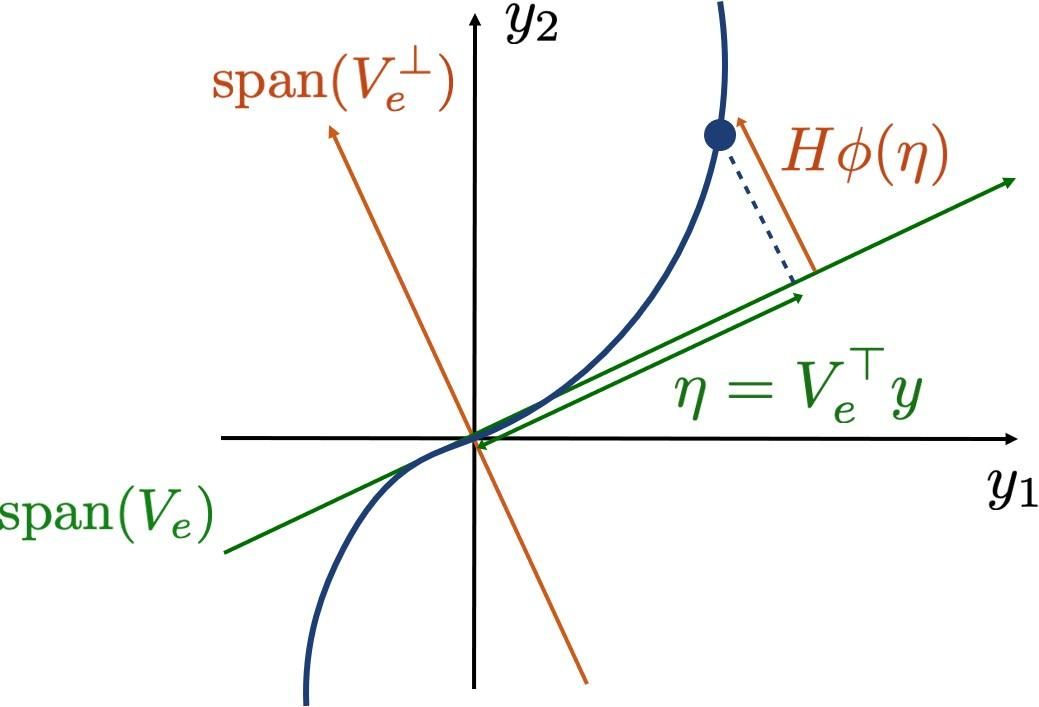

The manifold will be approximated up to order $M$. We therefore seek the $N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^T - H\phi_{m,2:M}(V_e^Ty_k) ||$$


to find $H$ and $V_e$, under the constraints that $V_e^T H=0$ and $V_e^T V_e = I$. This minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

[V, SSMFunction, H] = IMparametrization(data, SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.637042e-07    2.220e-16    4.924e-05
    1       2    3.552219e-07    8.075e-09    4.704e-05    9.308e-05
    2       3    3.190094e-07    1.879e-07    3.684e-05    4.494e-04
    3       4    2.443381e-07    3.333e-06    3.580e-05    1.898e-03
    4       5    2.358093e-07    6.173e-08    3.712e-05    2.804e-04
    5       6    1.898608e-07    8.872e-07    3.374e-05    1.204e-03
    6       7    1.294857e-07    2.852e-06    1.627e-05    2.479e-03
    7       8    1.230138e-07    2.750e-09    1.000e-05    3.104e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

## Plot and validation

We plot the computed manifold embedding and calculate the deviation of the test data from the reduced model to evaluate the quality of model predictions.

figure
hold on
meanDist = zeros(length(indTest),1);
Y = [];
for i = 1:length(indTest)
    iTraj = indTest(i);
    y = V'*xData{iTraj};
    plot(y(1,:), y(2,:))
    meanDist(i) = mean(vecnorm(xData{iTraj} - SSMFunction(y)));
end
RRMS = mean(meanDist)

RRMS = 4.3376e-04

RRMS is the root mean square error of the reconstruction.

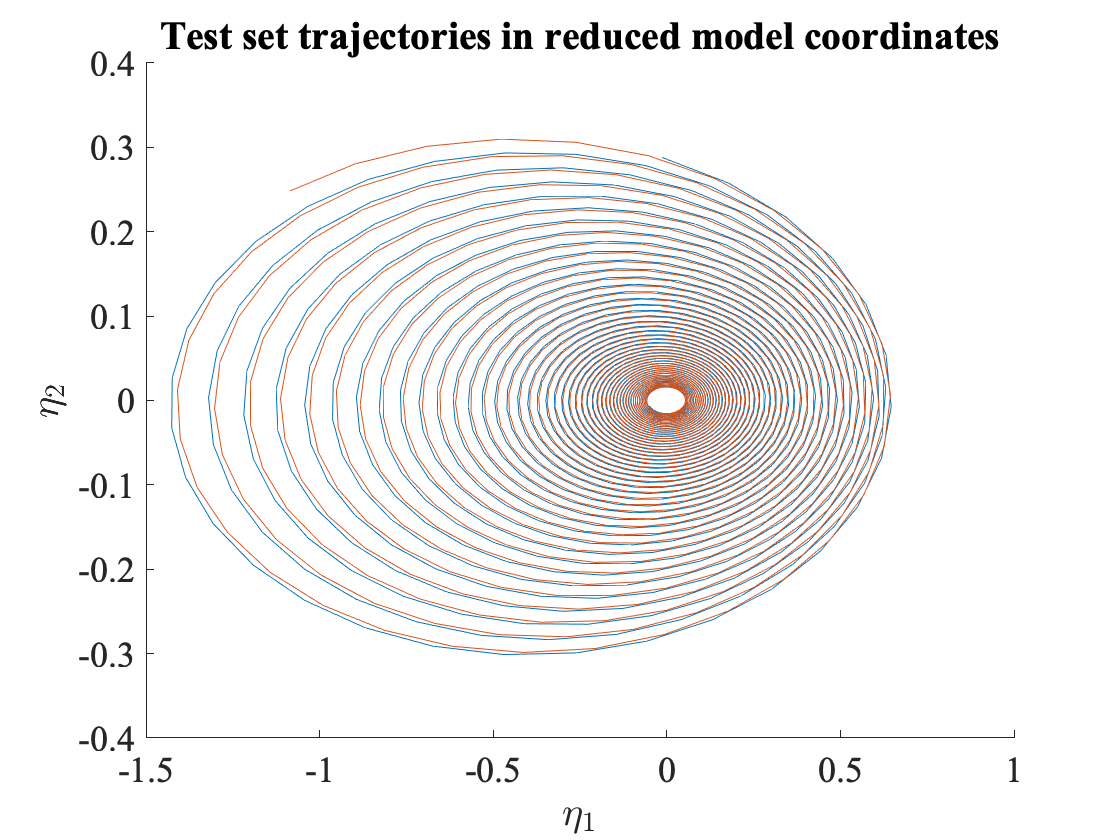

xlabel('$\eta_1$', 'Interpreter', 'latex')
ylabel('$\eta_2$', 'Interpreter', 'latex')
title('Test set trajectories in reduced model coordinates')
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)

For the first degree of freedom, we compare the full dynamics to the reduced model, where we have projected the trajectory onto the manifold.

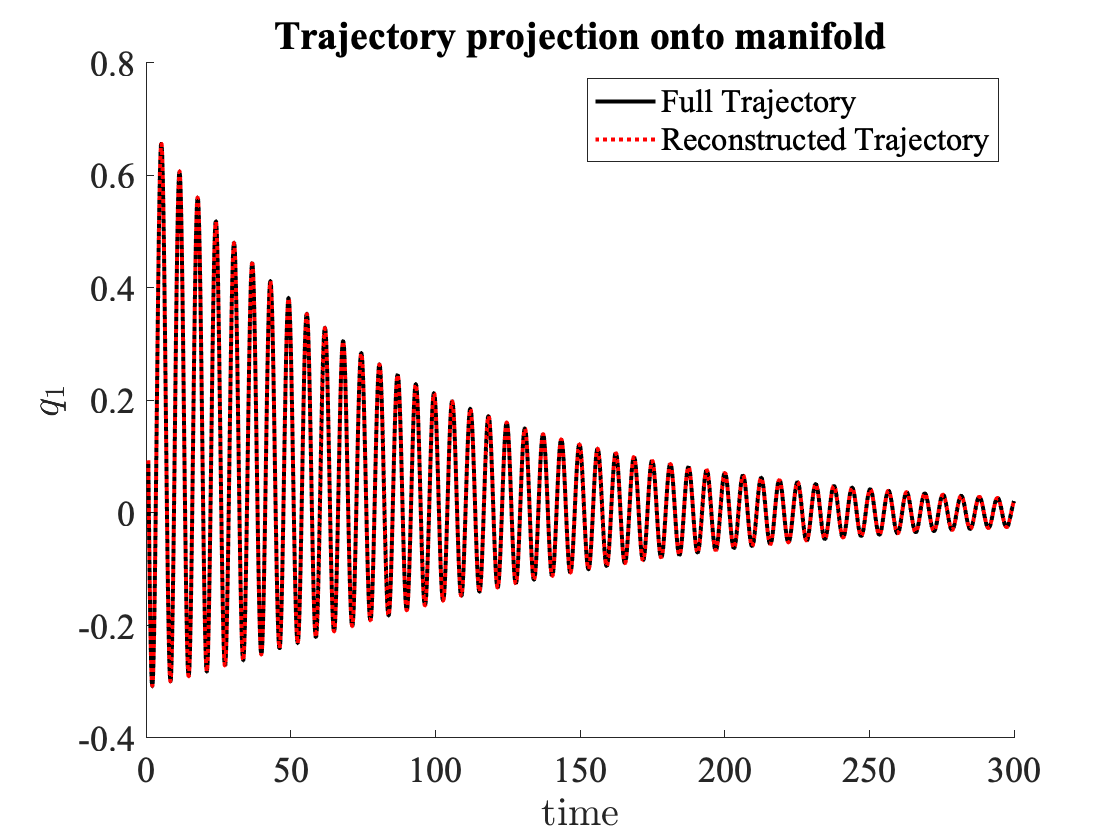

figure
hold on
plotCoord = 2;
plot(tData{indTest(1)}, xData{indTest(1)}(plotCoord,:),'k','Linewidth',2,'DisplayName','Full Trajectory')
xReconstructed = SSMFunction(V'*xData{indTest(1)});
plot(tData{indTest(1)}, xReconstructed(plotCoord,:),'r:','Linewidth',2,'DisplayName','Reconstructed Trajectory')

xlabel('time','Interpreter','latex')
ylabel('$q_1$','Interpreter','latex')
title('Trajectory projection onto manifold')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend

Furthermore, we draw the manifold shape along with the trajectories from the test set.

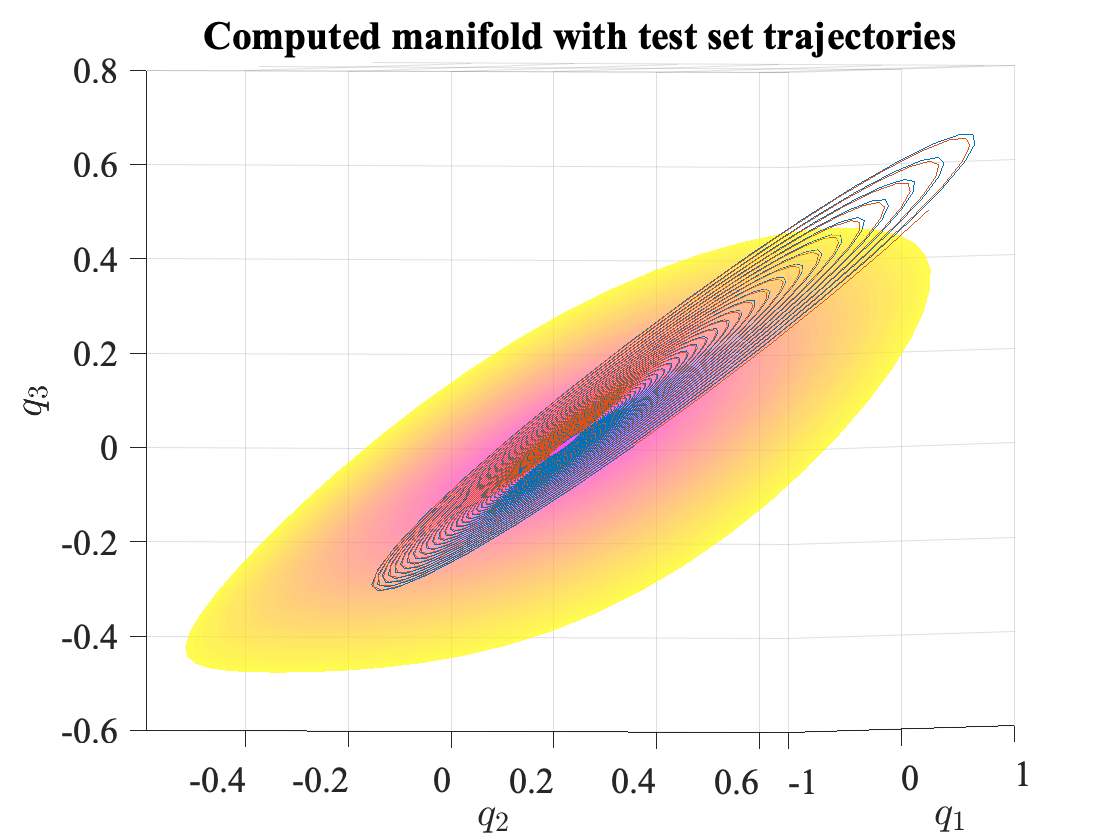

figure
hold on
plotRadius = 1;
plotInds = [1,2,3];
plotSSM(plotRadius, plotInds, SSMFunction);

for iTraj = indTest
    plot3(xData{iTraj}(plotInds(1),:), xData{iTraj}(plotInds(2),:), xData{iTraj}(plotInds(3),:))
end

xlabel(['$q_' num2str(plotInds(1)) '$'], 'Interpreter', 'latex')
ylabel(['$q_' num2str(plotInds(2)) '$'], 'Interpreter', 'latex')
zlabel(['$q_' num2str(plotInds(3)) '$'], 'Interpreter', 'latex')
title('Computed manifold with test set trajectories')
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)
grid on
view(50, 30)